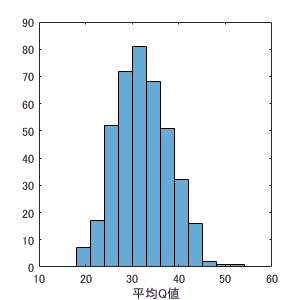

cd '\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_09_04_Qvalue_400samples'
load q_value.mat
ave_q_value = mean(q_value,2);
figure;
histogram(ave_q_value);
xlabel('平均Q値')
exportfig('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_09_04_Qvalue_400samples\hist_ave_qvalue','png',[300,300]);


cd \\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\medium\2018_08_28_realisticScatter
load rate_EMCLs.mat

cd \\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_08_28_realisticScatter
save('rateEMCL','rate_EMCLs')
save('q_value','q_value','ave_q_value')
load diff_point_each.mat



w = 1;
std_diff_point = std(diff_point_each,w)

std_diff_point =     4.6575    3.8523    4.2871    4.4054    4.2779    3.4699    3.5119    3.2250    3.3779    3.4655    3.5340    3.9215    3.9026    3.7791    3.9123    4.2363    4.1635    4.1393    4.1378    4.2615    4.3856    4.2035    3.9423    4.0966    4.0457    4.1596    4.3347    4.2812    4.4875    4.5811    4.3851    4.5911    4.7255    4.6076    4.9696    4.7833    4.6941    5.0221    4.9587    5.0165    4.9302    5.3102    5.3772    5.3499    5.2174    5.3235    5.4051    5.7153    6.0163    5.9891


ave_rate_EMCLs = mean(rate_EMCLs)

ave_rate_EMCLs = 25.3367

std_rate_EMCLs = std(rate_EMCLs,w)

std_rate_EMCLs = 4.1796

ave_ave_q_value = mean(ave_q_value)

ave_ave_q_value = 32.3020

std_ave_q_value = std(ave_q_value,w)

std_ave_q_value = 5.6965

var_ave_q_value = var(ave_q_value,w)

var_ave_q_value = 32.4496

cov_rateE_aveQ = cov(ave_q_value,rate_EMCLs)

cov_rateE_aveQ =    32.5310   -0.1497
   -0.1497   17.5126


cov_rateE_aveQ = cov_rateE_aveQ(1,2)

cov_rateE_aveQ = -0.1497

corr_rateE_aveQ = cov_rateE_aveQ/(std_rate_EMCLs*std_ave_q_value)

corr_rateE_aveQ = -0.0063

cov_diff_aveQ = cov(std_diff_point,ave_q_value);
cov_diff_aveQ = cov_diff_aveQ(1,2)

cov_diff_aveQ = 0.8486

std_std_diff_point = std(std_diff_point,w)

std_std_diff_point = 0.7374

corr_aveQ_diff = cov_diff_aveQ /(std_ave_q_value*std_std_diff_point)

corr_aveQ_diff = 0.2020